# Path Tracking

There are several ways  to make robot follows a path, in this lesson we present a simple algorithm (**PurePursuit**) that relys on follow an especifict point in the path, when the robot is away from a certain distance to that point, the robot change goal pose to the next pose in the path, this  process is repeat until reach the last pose in the path. 

Define a start and goal poses.

initPose = [ 0.5; 0.5; 1.5707]; % [x ; y ; theta]   
goalPose = [2, 2.5,0];

Prepare map  to calculate path

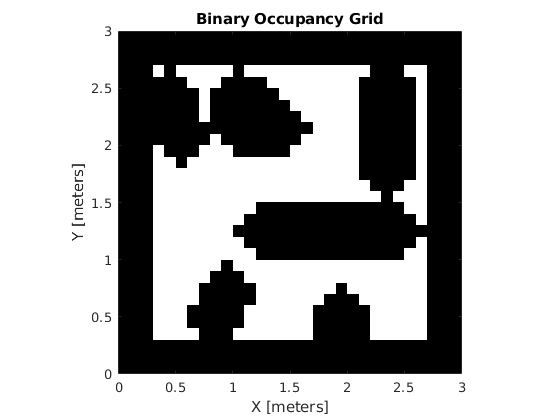

%Load an image, process it and convert it to binary Occupancy Map.
map = generateMap(which('world1.png'), 0.1, 10);
bounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];
ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.2;
image = imread(which('world1.png'));
grayimage = rgb2gray(image);
bwimage = grayimage < .1;

%morphological dilation
se = strel('sphere',2);
bwimage = imdilate(bwimage,se);

%Convert image into  binaryOccupancyMap  with scale  (pixes/meter).
mapDilatation = binaryOccupancyMap(bwimage,10);

show(mapDilatation)

Calculate path

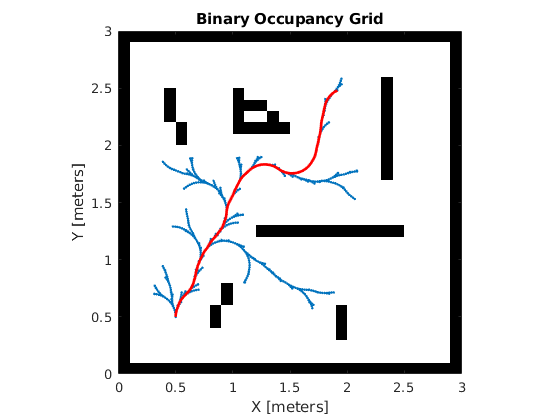

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = mapDilatation;
stateValidator.ValidationDistance = .1; %Planner cheks if there is an obstacle between this distance in the path.
planner = plannerRRTStar(ss, stateValidator);
planner.MaxConnectionDistance = .02;
planner.MaxIterations = 30000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;
rng(1,'twister')
[pthObj, solnInfo] = plan(planner, initPose.', goalPose);



show(map)
hold on
% Search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');
% Interpolate and plot path
interpolate(pthObj,300)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)
hold off

Define a differential robot.

viz = Visualizer2D;
viz.mapName = 'map';
viz.robotRadius = .12; 
R = 0.1; 
L = 0.12; 
mobileRobot = DifferentialDrive(R,L);

**Pure Pursuit** Controller for path tracking.  If you need more information about this controller  [check this link.](https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html) 

controller = controllerPurePursuit;
controller.Waypoints = [pthObj.States(:,1), pthObj.States(:,2) ]; %Waypoints are  the poses calculate by RRT algorithm  in this case We just use x and y 
controller.LookaheadDistance = .05;  %How far along the path the robot should look from the current location to compute the angular velocity commands
controller.DesiredLinearVelocity = 0.1;
controller.MaxAngularVelocity = pi/6;

Execute simulation.

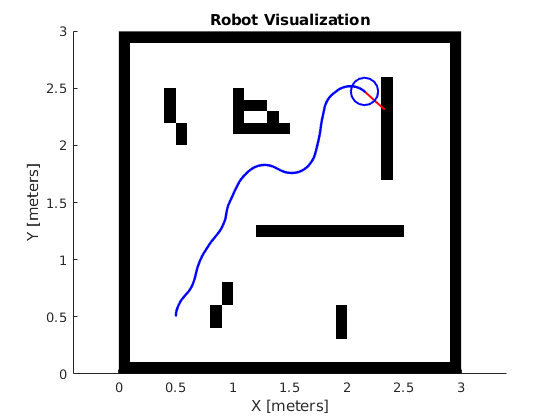

currentPose = initPose;
[sampleTime,tVec,r] = simulTime(0.1,30);
for idx = 2:numel(tVec) 
    
    [vRef,wRef,lookAheadPt] = controller(currentPose);
    bodyV = [vRef;0;wRef];
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
    
    % Update visualization
    viz(currentPose);

    %Wait for visualization rate
    waitfor(r);
    
end

# Practice

Change lookahead distance of purePersuit Controller for larger and shorter distances defined in this script. Analyze the resulting trajectories.

Change start and goal pose then choose the best lookahead distance from your point of view.

function isReached = exampleHelperCheckIfGoal(planner, goalState, newState)
    isReached = false;
    threshold = 0.1;
    if planner.StateSpace.distance(newState, goalState) < threshold
        isReached = true;
    end
end


